## Introduction

Par Bastian KROHG et Nicolas SIARD

4A AE-SE Groupe 1 - BE Trottinette 

## Fonction de Transfert en Boucle Ouverte

R = 1

R = 1

Km = 1/R

Km = 1

Khach = 48 

Khach = 48

Kcourant = 0.10416

Kcourant = 0.1042

Kf = 1.4569

Kf = 1.4569

K = Km*Khach*Kcourant*Kf %Gain global

K = 7.2840

ft = 400 

ft = 400


fm=80

fm = 80

tau_m = 1/(2*pi*fm)

tau_m = 0.0020


ff=2000

ff = 2000

tau_f = 1/(2*pi*ff)

tau_f = 7.9577e-05


tau_i = K/(2*pi*ft) 

tau_i = 0.0029

fi = 1/(2*pi*tau_i)

fi = 54.9146

tau_c = tau_m

tau_c = 0.0020


Gm=tf([Km], [tau_m 1])

Gm =
 
        1
  --------------
  0.001989 s + 1
 
Continuous-time transfer function.



F=tf([Kf], [tau_f 1])

F =
 
       1.457
  ---------------
  7.958e-05 s + 1
 
Continuous-time transfer function.



C=tf([tau_c 1],[tau_i 0])

C =
 
  0.001989 s + 1
  --------------
    0.002898 s
 
Continuous-time transfer function.




G=Khach*Kcourant*Gm*F*C

G =
 
              0.01449 s + 7.284
  ------------------------------------------
  4.588e-10 s^3 + 5.996e-06 s^2 + 0.002898 s
 
Continuous-time transfer function.



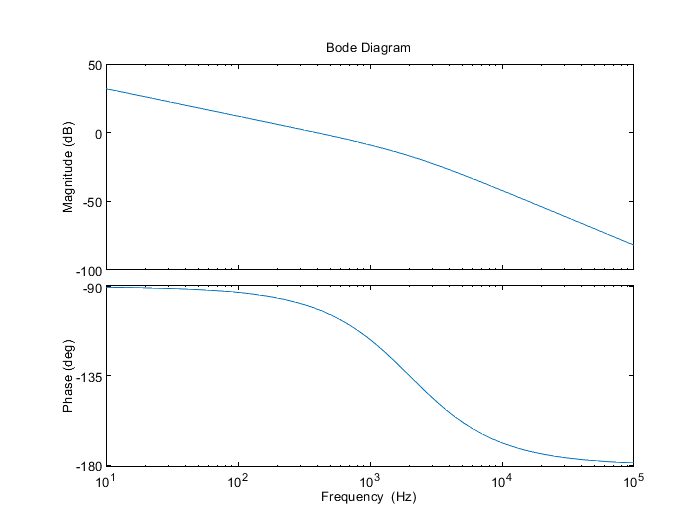

options = bodeoptions;
options.FreqUnits = 'Hz' ; %par defaut en rad/s
bode(G, options)

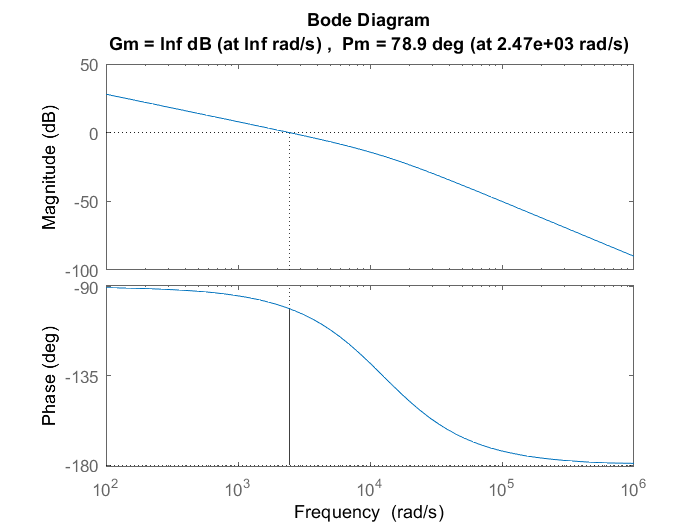

margin(G)


%sim("trottinette.slx")
%simout = out.simout

## Fonction de Transfert en Boucle Fermée

On a une grande marge de phase, permettant à notre systeme d'avoir une reponse à un echelon sans resonance/depassement. 

Pour changer la frequence de coupure en BF il faut modifier le tau_i afin de shifter la courbe et donc la frequence de transition.

FTBF = G/(1+G)

FTBF =
 
                 6.649e-12 s^4 + 9.024e-08 s^3 + 8.568e-05 s^2 + 0.02111 s
  ----------------------------------------------------------------------------------------
  2.105e-19 s^6 + 5.503e-15 s^5 + 4.527e-11 s^4 + 1.25e-07 s^3 + 9.408e-05 s^2 + 0.02111 s
 
Continuous-time transfer function.



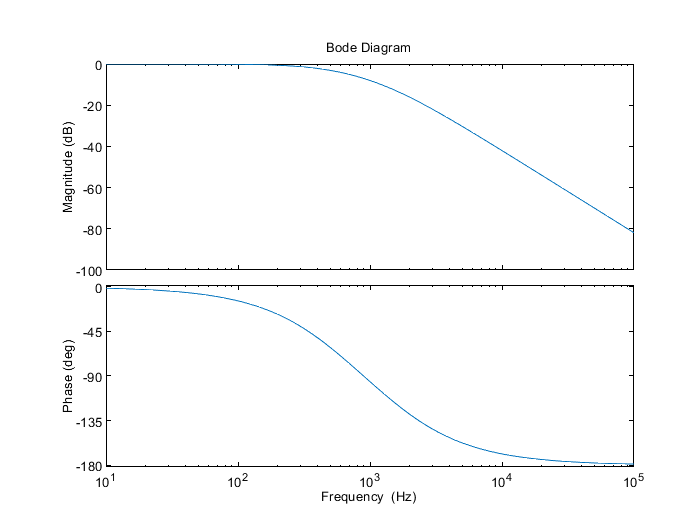

bode(FTBF, options)

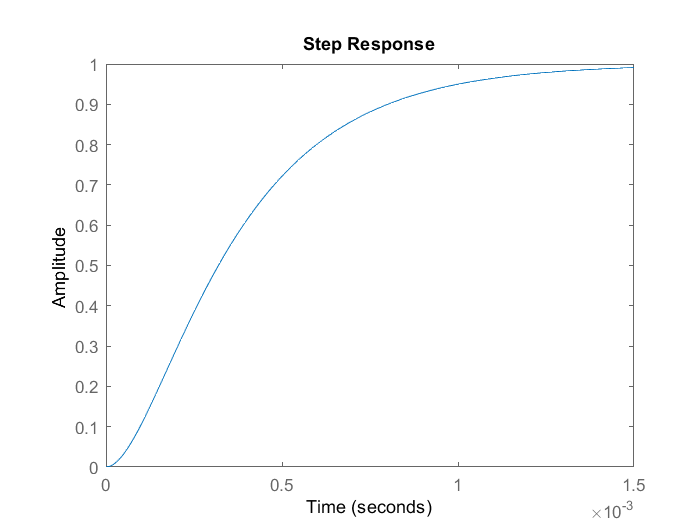

step(FTBF, 1.5e-3)

response_info = stepinfo(FTBF)

response_info = struct with fields:
        RiseTime: 7.0368e-04
    SettlingTime: 0.0013
     SettlingMin: 0.9034
     SettlingMax: 0.9998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9998
        PeakTime: 0.0026


## Saturateur

On ajoute un saturateur entre le correcteur C(p) et Gm(p) pour que alpha ne dépasse pas ±0.5

%sim("trottinette_v2.slx")
%simout = out.simout

## Passage au discret 

Calcul theorique de C(z)!

Avantages/inconvenients d'avoir Te petit/grand:

    Si Te trop petit:

         On va avoir des énergies trop élevées lorsque la fréquence augmente, ce qui dissipe davantage de la puissance et de la chaleur. De plus, on peut avoir un phenomene des interruptions qui ne s'effectuent pas assez rapidement, et la même interruption va etre pending et la commande ne s'effectuera plus en temps réel.

    Si Te trop grand:

        On va avoir des instabilités parce qu'on n'a pas assez de points pour bien discretiser le signal du système.

De C(p) à C(z)

On va vérifier la transformée en z du bloc correcteur C

%Vu qu'on a ft en BF est repoussée à environ 500Hz, il faut que Fe soit >= 2*fmax = 2*ft = 1000Hz. On le
%choisit à Fe = 1200Hz. On voit que si on teste le correcteur en simulation
%avec simulink avec Fe = 1000, il dépasse la limite de stabilité et on voit
%que la sortie oscille. 
Fe = 2000

Fe = 2000

Te = 1/Fe

Te = 5.0000e-04

methode =  'tustin'

methode = 'tustin'

C_z = c2d(C,Te,methode) 

C_z =
 
  0.7727 z - 0.6002
  -----------------
        z - 1
 
Sample time: 0.0005 seconds
Discrete-time transfer function.




%sim("trottinette_discret_v3.slx")
%simout = out.simout

%G_z =Khach*Kcourant*Gm*F*C_z
%FTBF_z = G_z/(1+G_z)
%step(FTBF_z, 1.5e-3)
%response_info = stepinfo(FTBF_z)

## Observer le phenomene induit par le saturateur:

Si on change (...) pour pousser le système à dépasser son Slew Rate et ainsi saturer lorsque l'erreur devient grande, ainsi faisant en sorte que l'alpha soit bloqué à 0.5 avant que le système revienne. Ce phenomene correspond à l'envol de l'integrateur. 

Avant, on a reglé le systeme afin qu'il se comporte comme un premier ordre, ne dépassant pas son slew rate et ne faisant pas apparaitre ce phenomene. A la suite, on va le mettre en evidence. 

Dans simulink: trottinette_discret_saturation_v4.slx

A Fe=2000Hz avec Step = 1.65 on observe un depassement dû a la saturation, ce qui est très visible en regardant le scope après le bloc correcteur C_z. Ici on voit que le signal alpha est bloqué à 0.5 pendant un certain temps.

Cependant, si on diminue la consigne à 0.5 et on augmente la Fe, on voit que le système ne presente plus ce defaut car le slew rate imposée devient plus rapide que le système, le laissant repondre sans saturer. 

 ****On ajoute un bloqueur d'ordre zéro pour définir le sample rate Te dans simulink. Normalement ce bloc n'a pas d'interet pour le système, il faut en rajouter un apres le C(z) afin de le laisser interragir avec le moteur qui fonctionne en continu. Cependant, le bloqueur apres le correcteur discret est geré directement par le bloc correcteur par simulink. *****

## La suite

- Correcteur numerique avec KEIL

- Verification en simulation

- Verification en reel

- Evolutions du projet: asservissement de vitesse (boucle externe) ou init avec determination des grandeurs physiques (tau_i, tau => R, L)